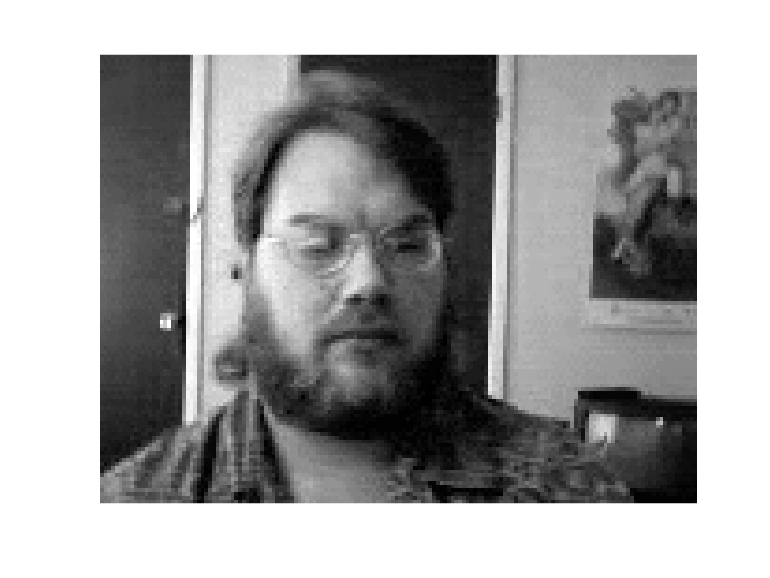

%% Sample script for the "author" data

% Some cleaning commands:
close all; clear; clc;

%Change this value to change the rank of the approximation.
k=2;

% The file author.mat is loaded here- Download it from Canvas.
load author
Y1=double(Y1);  %Changes the data from "integers" to "floating point"
                %The data was saved as integers to save on memory.

% We can visualize the "movie"
figure(1)
for j=1:109
   A=reshape(Y1(:,j),120,160);
   imagesc(A); colormap(gray); axis equal; axis off;
   pause(0.1)
end

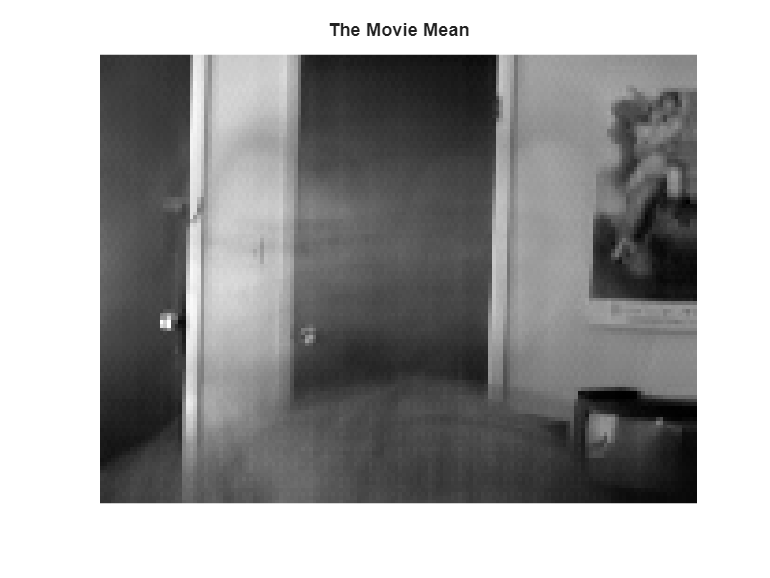


% Now that we've all had a good laugh, let's continue.

%% Mean subtraction and visualize the mean.
Ymean=mean(Y1,2);
figure(2)
imagesc(reshape(Ymean,120,160)); colormap(gray); axis equal; axis off;
title('The Movie Mean');

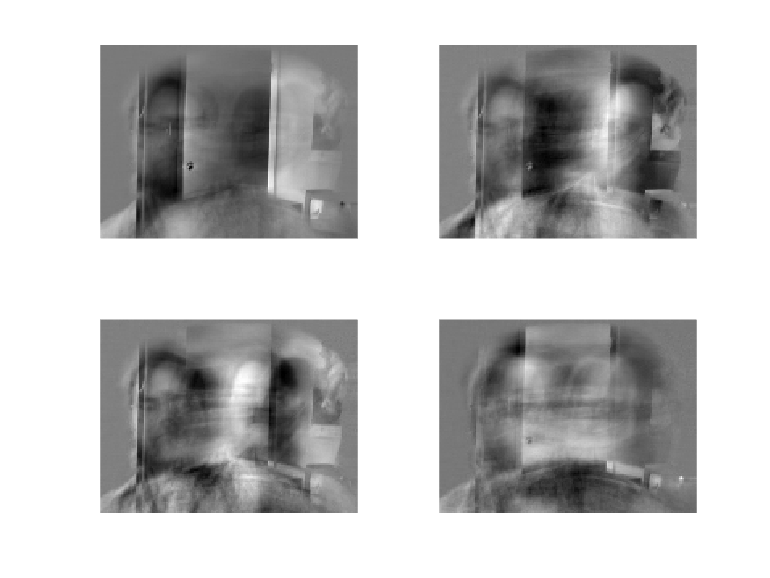


%% The SVD
% We'll mean subtract, but keep the original data intact.  We'll call put
% the mean subtracted data in matrix X.
X=Y1-repmat(Ymean,1,109);
[U,S,V]=svd(X,'econ');

%% Visualize the basis vectors- Here are 4 of them
figure(3)
for j=1:4
    subplot(2,2,j)
    imagesc(reshape(U(:,j),120,160)); colormap(gray); axis equal; axis off
end

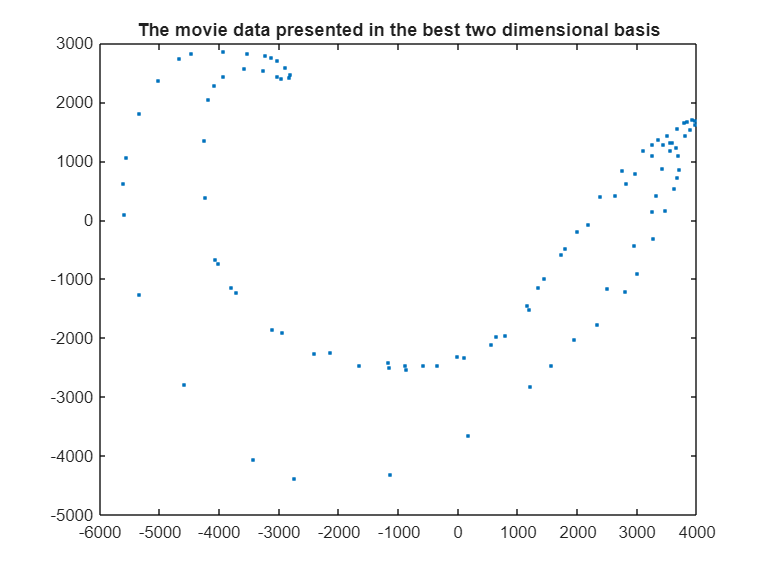


%% Projection to R^2
Xcoords=U(:,1:k)'*X;   %The matrix Xcoords is now 2 x 109

figure(4)
plot(Xcoords(1,:),Xcoords(2,:),'.');
title('The movie data presented in the best two dimensional basis');

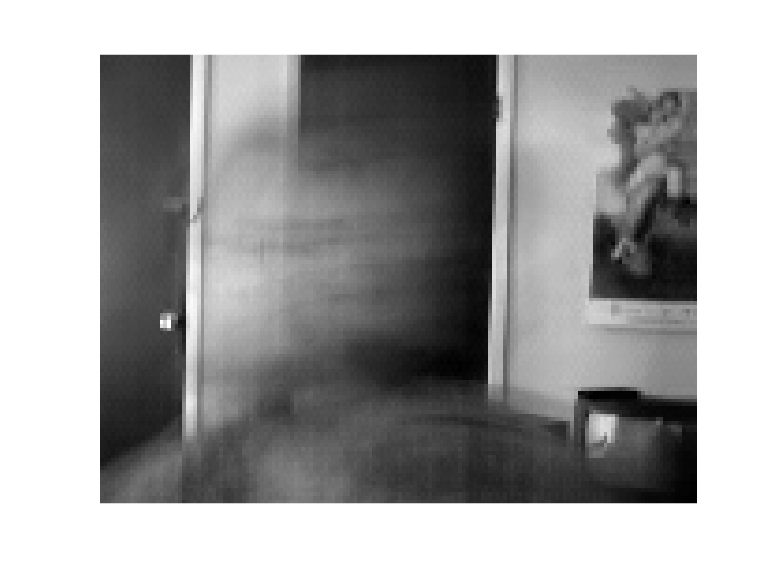


%% The Best two dimensional reconstruction as a movie
Recon=U(:,1:k)*Xcoords;

figure(5)
 for j=1:109
    A=reshape(Recon(:,j)+Ymean,120,160);
    imagesc(A); colormap(gray); axis equal; axis off;
    pause(0.05)
 end